clc;
clear all;
close all;

## Exercise 1

Ac = [0 1; 0 0];
Bc = [0; 1];
C = [1 0; 0 1; 0 0];
D = [0; 0; 1];
E = [1 0];
F = 0;
yub = [6, 2, 2]';
ylb = [-6, -2, -2]';
C = [C
    -C];
D = [D
    -D];
y = [yub
    -ylb];
ts = 0.1;

### Part A

sys_c = ss(Ac,Bc,[],[]);
sys_d = c2d(sys_c, ts);
A = sys_d.A

A =     1.0000    0.1000
         0    1.0000


B = sys_d.B

B =     0.0050
    0.1000


### Part B

G = null([A - eye(size(A)), B, zeros(size(B)); E, F, -eye(size(E, 1))])

G =     0.7071
   -0.0000
   -0.0000
    0.7071


Gx = G(1:length(A))

Gx =     0.7071
   -0.0000


Gu = G(length(A)+1 : length(A)+length(F))

Gu = -1.3764e-16

Gz = G(length(A)+length(F)+1:end)

Gz = 0.7071

Dividing with Gz to normalise the values

Gx = Gx/Gz;
Gu = Gu/Gz;
Gz = eye(size(Gz));

### Part C

x0 = [0;0];
ref = 5;
v = ref;

[n,m] = size(B);

Q = E'*E;
R = 1;
[K,P,~] = dlqr(A,B,Q,R);

% Prediction Horizon
N = 16; % N = 4 was very short. While the current one is suff. long

% Terminal Constraints (None)
% Ox = zeros(1,n);
% Ov = zeros(1,m);
% oy = 0;

% Terminal Constraints (O_infinity)
[Ox,Ov,oy] = calc_Oinf(A,B,C,D,K,y,Gx,Gu);

% Pad Ox with Zeros
Ox = [zeros(length(oy),N*m+(N-1)*n) Ox];

% QP, Sparse Formulation
In = eye(N);
In1 = diag(ones(N-1,1),-1);

H = blkdiag(kron(In,R),kron(eye(N-1),Q),P);
f = zeros(N*(n+m),1);
fnew = [repmat(R*Gu, N, 1); repmat(Q*Gx, (N-1), 1); P*Gx];

E  = [kron(In,B) kron(In1,A)-eye(N*n)];
gx = [-A;zeros((N-1)*n,n)];

Y  = [kron(In,D) kron(In1,C)];
yx = [-C;zeros((N-1)*length(y),n)];
yc = kron(ones(N,1),y);

out = sim('HW_4_Q1.slx');

% Plots
t = out.tout;
x0 = out.x0';
u0 = out.u0';
V0 = out.V0';
x = out.x';
u = out.u';
V = out.V';
x1 = out.x1';
u1 = out.u1';
V1 = out.V1';

### Part D & E

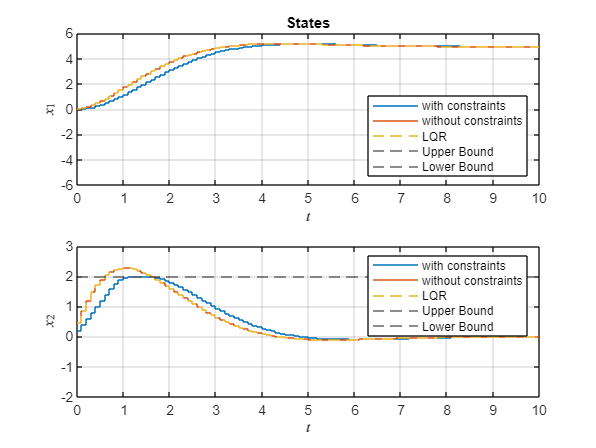

figure
subplot(2,1,1)
stairs(t,x(1,:)); hold on;
stairs(t,x1(1,:));
stairs(t,x0(1,:),'--');
yline(yub(1), '--');
yline(ylb(1), '--'); hold off; grid on;
xlabel('$t$','Interpreter',"latex")
ylabel('$x_1$','Interpreter',"latex")
legend('with constraints','without constraints','LQR','Upper Bound', 'Lower Bound','Location','southeast')
title('States')

subplot(2,1,2)
stairs(t,x(2,:)); hold on;
stairs(t,x1(2,:));
stairs(t,x0(2,:),'--');
yline(yub(2), '--');
yline(ylb(2), '--'); hold off; grid on;
xlabel('$t$','Interpreter',"latex")
ylabel('$x_2$','Interpreter',"latex")
legend('with constraints','without constraints','LQR','Upper Bound', 'Lower Bound')

The trajectories of the state variables $x_1$ and $x_2$ demonstrate the imapct of implementing constraints. The MPC with the constraints successfully keep the state variables within the specified bounds, while the unconstrained MPC allows for the excrusions beyond these limits. There is no difference observed between the states of LQR and MPC without constraints.

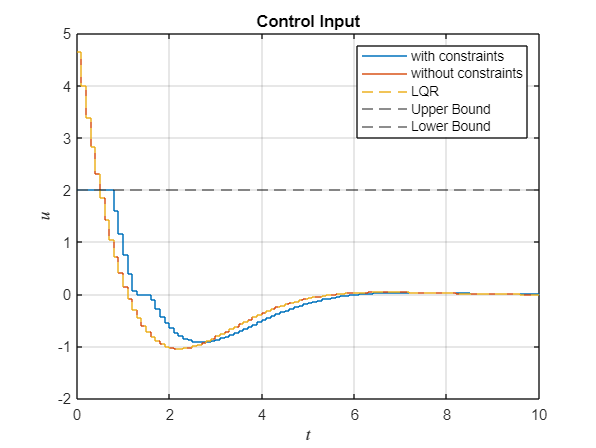

figure
stairs(t,u); hold on;
stairs(t,u1);
stairs(t,u0,'--');
yline(yub(3), '--');
yline(ylb(3), '--'); hold off; grid on;
xlabel('$t$','Interpreter',"latex")
ylabel('$u$','Interpreter',"latex")
legend('with constraints','without constraints','LQR','Upper Bound', 'Lower Bound')
title('Control Input')

The control input $u$ is depicted over time. The unconstrained MPC and LQR applies larger controller effort that exceeds the prescribed bounds, higlighting of the constraints in preventing such violations. While the MPC with constraints does not violate the control input bounds.

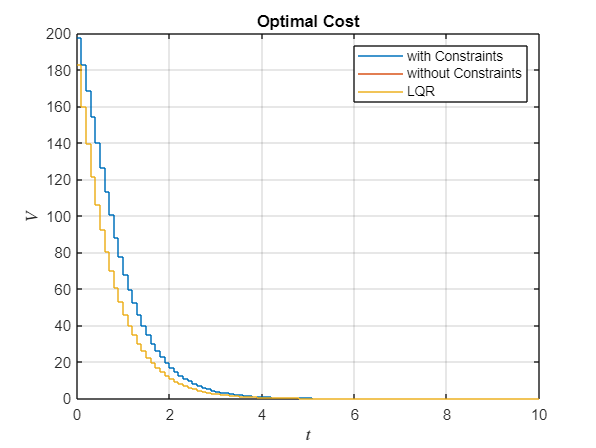

figure
stairs(t,V(1,:))
hold on; grid on
stairs(t,V1(1,:))
stairs(t,V0(1,:))
xlabel('$t$','Interpreter',"latex")
ylabel('$V$','Interpreter',"latex")
legend('with Constraints','without Constraints','LQR')
title('Optimal Cost')

Both constrained and unconstrained MPC have higher costs than LQR. Initially, unconstrained MPC has higher cost due to it's quick response and constrained MPC has lower cost due to slow response but after t=4 when both responses reach the desired states they have same cost, this can be corellated (goes parallel) with step response.

### Constraint Violations:

Notably, the unconstrained MPC allows for states and control inputs to surpass operational limits. These excesses stem from the controller's prioritization of rapid state change over compliance with constraints. In the absence of bounds, the controlles effort tends to be aggressive , potentially breaching physical or safety thresholds in real-world applications.

# Auxiliary Functions

function [Ox,Ov,oy] = calc_Oinf(A_ol,B_ol,C_ol,D_ol,K,y,Gx,Gu)

% Steady-State Manifold
% G = null([A_ol-eye(size(A_ol)) B_ol]);
% Gx = G(1:size(A_ol,2),:);
% Gu = G(size(A_ol,2)+1:end,:);

% Closed Loop System
A = A_ol-B_ol*K;
B = B_ol*(Gu+K*Gx);
C = C_ol-D_ol*K;
D = D_ol*(Gu+K*Gx);

% Steady-State Constraints
eps = 0.05;
Hss = [0*C C*Gx+D];
hss = (1-eps)*y;

% 0-step Constraint Admissible Set
H0 = [C D];
h0 = y;

Oinf = Polyhedron([Hss;H0],[hss;h0]);

while isempty(h0)~=1
    % Plot Polyhedron
    % Oinf.plot
    % xlabel('$x_1$','Interpreter','latex')
    % ylabel('$x_2$','Interpreter','latex')
    % zlabel('$v$','Interpreter','latex')
    % axis equal
    % pause(0.01)
    
    % Update Constraints
    H1 = H0*[A B; zeros(size(B')) eye(size(B,2))];
    h1 = h0;
    
    % Eliminate Redundant Rows
    [H1,h1] = elim_redundancies(Oinf,H1,h1);
    
    % Update the Polyhedron
    Oinf = Polyhedron([Oinf.A; H1],[Oinf.b; h1]);

    % Reinitialize Iteration
    H0 = H1;
    h0 = h1;
end
% Oinf Constraints
Ox = Oinf.A(:,1:2);
Ov = Oinf.A(:,3);
oy = Oinf.b;
end

function [H_nred,h_nred] = elim_redundancies(poly,H,h)
% Nonredundant Constraints
H_nred = [];
h_nred = [];

for i = 1:length(h)
    % Check Redundancy for each individual row
    f = -H(i,:)';
    
    A = [poly.A
         H((1:length(h))~=i,:)];
    
    b = [poly.b
         h((1:length(h))~=i,:)];
    
    % Solve LP
    [~,fval,flag]=linprog(f,A,b,[],[],[],[],optimoptions('linprog','Display','none'));
    
    if flag == -3 || -fval>h(i)
        % Constraint is not redundant
        H_nred = [H_nred;H(i,:)];
        h_nred = [h_nred;h(i)];
    end
    
end

end